clear
N = 5; % 40 390
gen_nodes1 = [0,0;0,0.04;0.2,0.04;0.2,0];
[Ele_Nodes1,Nodes1,posNode1,A1,Total1] = nodeCoordinates(gen_nodes1,N);

el_sidex = 0.0400

gen_nodes2 = [0.08,0.04;0.08,0.1;0.1,0.120;0.120,0.04];
[Ele_Nodes2,Nodes2,posNode2,A2,Total2] = nodeCoordinates(gen_nodes2,N/3);

el_sidex = 0.0400

test = A1+1

test = 6

test2 = A2+1

test2 = 2

Nodes2(1:test2,:) = [];
Nodes_Global = [Nodes1;Nodes2];

%}
test4 = posNode2+size(Nodes1,1)-test2;
test4(1:A2,1:2) = test4(1:A2,flip([3,4]))-round((test+test2)/2);
Pos_Global = [posNode1;test4];

for i = 1:Total1+Total2
    
    Ele_Nodes(1:4,i*2-1:i*2) = Nodes_Global(Pos_Global(i,:),:);
    
end

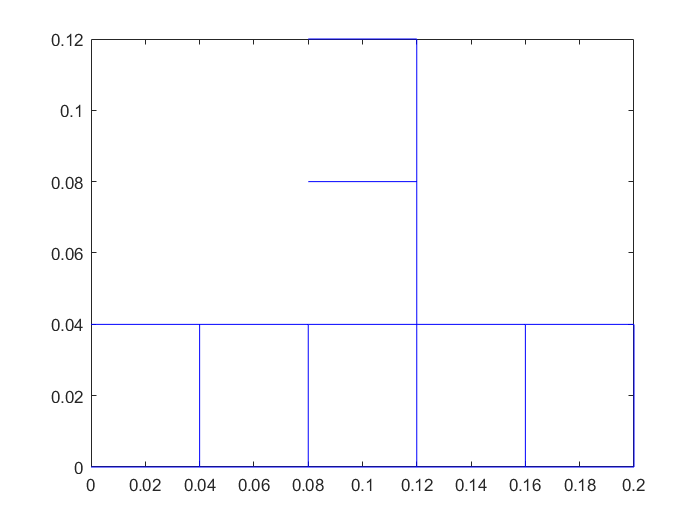

figure
for ele = 1:Total1+Total2
    plot(Ele_Nodes(:,ele*2-1),Ele_Nodes(:,ele*2),'b-')
    %text(Ele_Nodes(1,ele*2-1),Ele_Nodes(1,ele*2),num2str(ele))
    hold on
end